%%%% Data to sound test file with self-generated data

% % %% Portion of script that plays sound once target is detected in angle range. Uses hypothetical data matrix of target's angle and distance from the radar
% ydata = rand(10,2) + 1i*rand(10,2)
% rx_angle = angle(ydata)*(180/pi)
% target_angle = zeros(10,1);
% for i = 1:1:10
%     target_angle(i,1) = rx_angle(i,1) - rx_angle(i,2)
%     if (target_angle(i) > 0) || (target_angle(i) < 0)
%         play(player); % Refers to chosen audio file at beginning of code
%         pause(2) % wait 10 seconds before moving on to the next line
%     else
%         stop(player); % Refers to chosen audio file at beginning of code
%         pause(10) % wait 10 seconds before moving on to the next line
%     end
% end
% stop(player)

%% Data to sound test file - part 2 - plays certain pitches of a guitar string as the angle beamwidth changes. Uses hypothetical data matrix of target's angle and distance from the radar
ydata = rand(10,2) + 1i*rand(10,2)

ydata =    0.9038 + 0.3555i   0.2755 + 0.2000i
   0.5404 + 0.3629i   0.9516 + 0.9600i
   0.8179 + 0.0685i   0.3467 + 0.6651i
   0.7084 + 0.8672i   0.2973 + 0.5413i
   0.0432 + 0.4579i   0.4044 + 0.8690i
   0.1459 + 0.0776i   0.3022 + 0.5570i
   0.2333 + 0.9049i   0.7573 + 0.0214i
   0.2467 + 0.2817i   0.3597 + 0.4827i
   0.1703 + 0.6139i   0.1249 + 0.8080i
   0.2351 + 0.6619i   0.6172 + 0.7360i


rx_angle = angle(ydata)*(180/pi)

rx_angle =    21.4729   35.9851
   33.8869   45.2512
    4.7868   62.4703
   50.7533   61.2212
   84.6093   65.0423
   28.0044   61.5171
   75.5411    1.6185
   48.7891   53.3027
   74.4966   81.2127
   70.4477   50.0184


target_angle =   -14.5122
         0
         0
         0
         0
         0
         0
         0
         0
         0


target_angle =   -14.5122
  -11.3643
         0
         0
         0
         0
         0
         0
         0
         0


target_angle =   -14.5122
  -11.3643
  -57.6835
         0
         0
         0
         0
         0
         0
         0


target_angle =   -14.5122
  -11.3643
  -57.6835
  -10.4678
         0
         0
         0
         0
         0
         0


target_angle =   -14.5122
  -11.3643
  -57.6835
  -10.4678
   19.5670
         0
         0
         0
         0
         0


target_angle =   -14.5122
  -11.3643
  -57.6835
  -10.4678
   19.5670
  -33.5126
         0
         0
         0
         0


target_angle =   -14.5122
  -11.3643
  -57.6835
  -10.4678
   19.5670
  -33.5126
   73.9226
         0
         0
         0


target_angle =   -14.5122
  -11.3643
  -57.6835
  -10.4678
   19.5670
  -33.5126
   73.9226
   -4.5136
         0
         0


target_angle =   -14.5122
  -11.3643
  -57.6835
  -10.4678
   19.5670
  -33.5126
   73.9226
   -4.5136
   -6.7161
         0


target_angle =   -14.5122
  -11.3643
  -57.6835
  -10.4678
   19.5670
  -33.5126
   73.9226
   -4.5136
   -6.7161
   20.4293


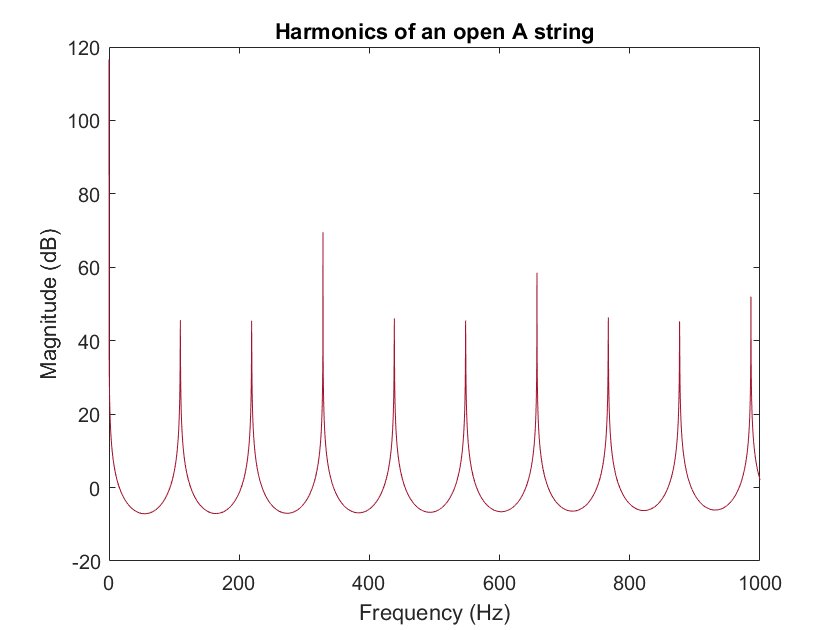

target_angle = zeros(10,1);
syms fret_value
for i = 1:1:10
    target_angle(i,1) = rx_angle(i,1) - rx_angle(i,2)
    if (target_angle(i,1) >= 13) && (target_angle(i,1) < 38)
        fret_value = 15;
    elseif (target_angle(i,1) >= -38) && (target_angle(i,1) < -13)
        fret_value = 5;
    elseif (target_angle(i,1) >= -13) && (target_angle(i,1) < 13)
        fret_value = 10;
    end
    if (target_angle(i,1)>-25) && (target_angle(i,1)<25)
        Fs       = 44100;
        A        = 110; % The A string of a guitar is normally tuned to 110 Hz
        Eoffset  = -5;
        Doffset  = 5;
        Goffset  = 10;
        Boffset  = 14;
        E2offset = 19;
        F = linspace(1/Fs, 1000, 2^12);
        x = zeros(Fs*4, 1);
        delay = round(Fs/A);
        b  = firls(42, [0 1/delay 2/delay 1], [0 0 1 1]);
        a  = [1 zeros(1, delay) -0.5 -0.5];
        [H,W] = freqz(b, a, F, Fs);
        plot(W, 20*log10(abs(H)));
        title('Harmonics of an open A string');
        xlabel('Frequency (Hz)');
        ylabel('Magnitude (dB)');
        zi = rand(max(length(b),length(a))-1,1);
        note = filter(b, a, x, zi);
        note = note-mean(note);
        note = note/max(abs(note));
        % hplayer = audioplayer(note, Fs); play(hplayer)
        
        fret  = 4;
        delay = round(Fs/(A*2^(fret/fret_value)));
        
        b  = firls(42, [0 1/delay 2/delay 1], [0 0 1 1]);
        a  = [1 zeros(1, delay) -0.5 -0.5];
        
        [H,W] = freqz(b, a, F, Fs);
        hold on
%         plot(W, 20*log10(abs(H)));
%         title('Harmonics of the A string');
%         legend(['Open A string'], ['A string on the ',num2str(fret_value),' fret']);
        zi = rand(max(length(b),length(a))-1,1);
        note = filter(b, a, x, zi);
        note = note-mean(note);
        note = note/max(note);
        hplayer = audioplayer(note, Fs); play(hplayer)
        pause(2)
    end
end